clc
clear

## normalize

im1 = read_image(12,true);

Rec-000020 - Copy - test_12.tif


% im2 = read_image(10,true);

im1_woBg = removeBackground(im1)

im1_woBg = 512×640 single matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0    

% im2_woBg = removeBackground(im2)

sensitivity = 0.4

sensitivity = 0.4000

[im1d, im1d_binarize] = apply_filter(im1_woBg,0.4);

% myshow('imtool',im1_woBg, im1d, im1d_binarize)

% myshow('imtool',im1d_binarize)

im1d2 = imhmax(im1d,0.4);
watershed_output = watershed(im1d2,8);
% c = label2rgb(D,'jet','w');
% myshow('imshow',im1d2, D, im1d_binarize)
% c = label2rgb(D,'jet','w')

mask = keeping_the_watershed_area(watershed_output, im1d_binarize);


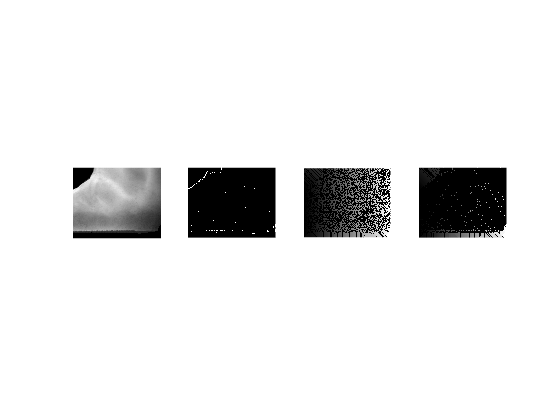


% myshow('imshow',im1_woBg, im1d_binarize, D, mask)

function myshow(mode,varargin)
    for x = 1:length(varargin)
        if strcmp(mode,'imshow')
            ax(x) = subplot(1,length(varargin),x); imshow(varargin{x},[]);% title('im1')
        elseif strcmp(mode,'imtool')
            ax(x) = subplot(1,length(varargin),x); imtool(varargin{x},[]);% title('im1')
        end
    end
    linkaxes(ax)

end

function im1_woBg = removeBackground(im1)
    im1b = im1*0;
    im1b(im1 < 0.1) = 1;
    im1b = imclose(im1b,strel('disk',20));
    
    im1_woBg = im1;
    im1_woBg(im1b==1) = 0;
    
    im1_woBg = func_normalize(im1_woBg - 0.1, 1);
    
end

function im = read_image(index, normalize)

dir = 'F:\Datasets\FLIR\video sample\tif\';
name = ['Rec-000020 - Copy - test_',int2str(index),'.tif'];
disp(name)
Dirr = [dir, name];
im = imread(Dirr);

if normalize
    im = func_normalize(im,1);
end

end

function im = func_normalize(im,type)
    mn = min(im(:));
    mx = max(im(:));
    if type == 16
        im = uint16(  (im-mn)*(2^16)/(mx-mn)  );
    elseif type == 8
        im = uint8(  (im-mn)*(2^8)/(mx-mn)  );
    elseif type == 1
        im = (im-mn)/(mx-mn);        
    end
    
    % im1c = histeq(im1_woBg,50);
    % im2 = adaptthresh(im1,'NeighborhoodSize',[3,3], 'ForegroundPolarity','dark', 'Statistic','median');
    
end

function [im1d, im1d_binarize] = apply_filter(im1_woBg,sensitivity)
    % local differentiation
    h = [-1,-1,-1;-1,8,-1;-1,-1,-1];
    im1c = filter2(h,im1_woBg,"valid");
    im1c = func_normalize(im1c, 1);
    
    % local average
    h = ones(3,3)/4;
    im1d = filter2(h,im1c,"valid");
    im1d = func_normalize(im1d, 1);
    
    im1d_binarize = ~imbinarize(im1d,'adaptive','ForegroundPolarity','dark','Sensitivity',sensitivity);
end

function mask = keeping_the_watershed_area(watershed_output, binary_mask)

    watershed_output(binary_mask == 0) = 0;
    c = unique(watershed_output(:));
    c(c == 0) = [];
    
    obj = regionprops(watershed_output,'Area','PixelIdxList');
    
    mask = watershed_output*0;
    for i = 1:length(c)
        mask(obj(c(i)).PixelIdxList) = c(i);
    end
end